addpath('rawData\')
%load data_1.mat
idx_start_time =1;
load('rawData\data_1.mat');

%暂时先只处理0.01s
seq_sur1=seq_sur(1:(length(seq_sur)/50));
seq_ref1=seq_ref(1:(length(seq_sur)/50));
duration1=0.01;

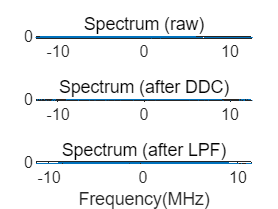

f1 =    -12500000   -12499900   -12499800   -12499700   -12499600   -12499500   -12499400   -12499300   -12499200   -12499100   -12499000   -12498900   -12498800   -12498700   -12498600   -12498500   -12498400   -12498300   -12498200   -12498100   -12498000   -12497900   -12497800   -12497700   -12497600   -12497500   -12497400   -12497300   -12497200   -12497100   -12497000   -12496900   -12496800   -12496700   -12496600   -12496500   -12496400   -12496300   -12496200   -12496100   -12496000   -12495900   -12495800   -12495700   -12495600   -12495500   -12495400   -12495300   -12495200   -12495100


H1 =   -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i


drawSpectrum(seq_ref1,f_s)
drawDDCSpectrum(seq_ref1,f_s)
[f1,H1]=AfterLPFSpectrum(seq_ref1,f_s);

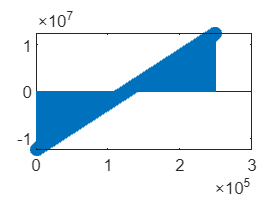

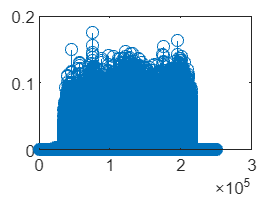

function [f,H]=AfterLPFSpectrum(x,fs)

    N=length(x);
    f_ddc=-3e6;
    H=fftshift(fft(x));
    H=circshift(H,-f_ddc/fs*N);
    f=(-N/2:N/2-1)*fs/N;

    [b,a]=butter(4,9e6/(fs/2),'low');[Hf,~]=freqz(b,a,N/2);
    H_all=[flip(Hf);Hf];
    Norm=norm(H);
    H=H.*H_all';
    H=H./norm(H).*Norm;
    subplot(3,1,3),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-80,0]),xlabel('Frequency(MHz)')
    title('Spectrum (after LPF)')
end

function drawSpectrum(x,fs)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    figure,subplot(3,1,1),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-80,0])
    title('Spectrum (raw)')
end

function drawDDCSpectrum(x,fs)
    N=length(x);
    f_ddc=-3e6;
    H=fftshift(fft(x));
    H=circshift(H,-f_ddc/fs*N);
    f=(-N/2:N/2-1)*fs/N;
    subplot(3,1,2),plot(f./10^6,20*log10(abs(H)))
    ylabel('Amplitude(dB)'),ylim([-80,0])
    title('Spectrum (after DDC)')
end

